close all; % Close all figures (except those of imtool.)
clear; % Erase all existing variables. Or clearvars if you want.
figure;
workspace; % Make sure the workspace panel is showing.
format long g;
format compact;
fontSize = 20;
markerSize = 40;

% READ IN IMAGE
[fileName, pathName] = uigetfile('*.*');
grayImage = importdata([pathName, fileName]);
[~, ~, numberOfColorChannels] = size(grayImage);
if numberOfColorChannels > 1
    grayImage = grayImage(:, :, 1);
end

% Display the image.
subplot(2, 3, 1);
Kmedian = medfilt2(grayImage); %preprocessing
Contrast = imadjust(Kmedian) ;
imshow(Contrast, []);
impixelinfo;
axis('on', 'image');
title('Original Image', 'FontSize', fontSize, 'Interpreter', 'None');
hold on
drawnow;

% Maximize window.
B = gcf;
g.WindowState = 'maximized';
drawnow;

% Get rid of garbage in last two rows because the poster posted
% a screenshot instead of the actual image.
grayImage(end - 1, :) = grayImage(end - 2, :);
grayImage(end, :) = grayImage(end - 2, :);

%% Extract the middle
col1 = 200;
col2 = 600;
rows1 = 210;
rows2 = 370;
xline(col1, 'Color', 'r', 'LineWidth', 2)
xline(col2, 'Color', 'r', 'LineWidth', 2)
yline(rows1,'Color', 'r', 'LineWidth', 2)
yline(rows2,'Color', 'r', 'LineWidth', 2)
graylmage = grayImage(rows1:rows2, col1:col2);

% Display the image.
subplot(2, 3, 2);
imshow(grayImage, []);
impixelinfo;
axis('on', 'image');
title('Cropped Image', 'FontSize', fontSize, 'Interpreter', 'None');

%% Need to background correct so we can do a global threshold.
verticalProfile = mean(grayImage, 2); % Mean of Matrix Rows
subplot(2, 3, 3);
plot(verticalProfile, 'b-', 'LineWidth', 2);
grid on;
hold on;
verticalProfile = movmax(verticalProfile, 13); %moving maximum
plot(verticalProfile, 'r-', 'LineWidth', 2);

% Fit to a quadratic.
xFit = 1 : length(verticalProfile);
coefficients = polyfit(xFit, verticalProfile, 6); %coefficients

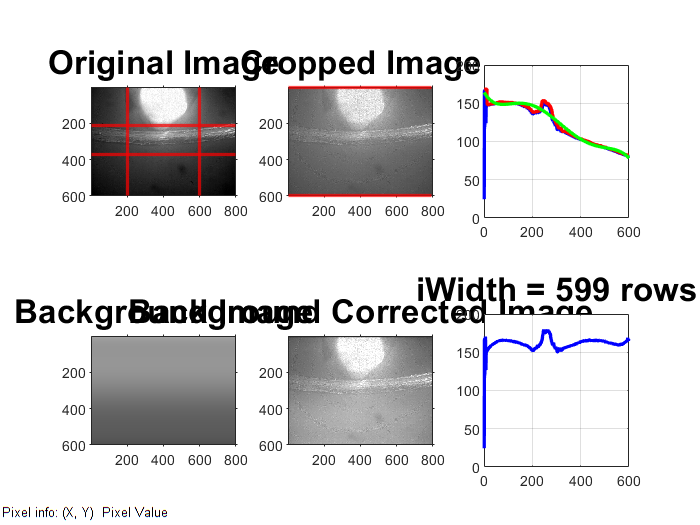

[rows, columns] = size(grayImage);
yFit = polyval(coefficients, xFit); %polyval
plot(yFit, 'g-', 'LineWidth', 2);

%% Divide image by the background.
backgroundImage = repmat(yFit(:), [1, columns]);

% Display the image.
subplot(2, 3, 4);
imshow(backgroundImage, [0, 255]);
impixelinfo;
axis('on', 'image');
title('Background Image', 'FontSize', fontSize, 'Interpreter', 'None');

%% Display the background corrected image.
subplot(2, 3, 5);
grayImage = uint8(max(backgroundImage(:)) * double(grayImage) ./ backgroundImage);
imshow(grayImage, [0, 255]);
impixelinfo;
axis('on', 'image');
title('Background Corrected Image', 'FontSize', fontSize, 'Interpreter', 'None');

verticalProfile = mean(grayImage, 2); %mean of current gray image (background corrected image)
subplot(2, 3, 6);
plot(verticalProfile, 'b-', 'Linewidth', 2);
grid on;

stats = graycoprops(grayImage) ;
% Find where the intensity falls below threshold.
threshold = 175;
rowl = find(verticalProfile < threshold, 1, 'first');
row2 = find(verticalProfile < threshold, 1, 'last');
width = row2 - rowl;
caption = sprintf('iWidth = %d rows', width);
title(caption, 'FontSize', fontSize, 'Interpreter', 'None');

% Draw on image #2
subplot(2, 3, 2);
yline(rowl, 'Color', 'r', 'LineWidth', 2)
yline(row2, 'Color', 'r', 'LineWidth', 2)